## No.2 Do Exercise 8

% Given the data
m = [-0.4326 -1.6656 0.1253 0.2877 -1.1465 1.1909 1.1892 -0.0376 0.3273 0.1746];
n = length(m);

### Find the sample mean

mbar = mean(m)

mbar = 0.0013

### Find the standard deviation

s = std(m)

s = 0.9034

### Construct a 95% confidence interval for the mean

ci = 0.95;
top = 1 - (1 - ci)/2;
bottom = (1 - ci)/2;
t_top = tinv(top,n-1);
t_bottom = tinv(bottom,n-1);

% confidence intervals
c1 = mbar + t_bottom*s/sqrt(n);
c2 = mbar + t_top*s/sqrt(n);

cofidence_interval = [c1 c2]

cofidence_interval =    -0.6450    0.6475


## No.3

### a). Plot a histogram of the 1000 average

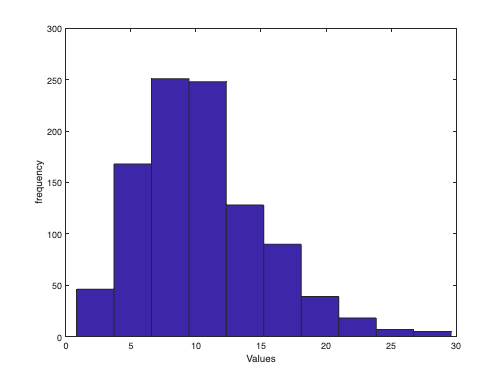

n3 = 5; % 5 exponentially distributed random numbers

[mbare3] = generate(n3);

% plot a histogram
figure(1)
hist(mbare3)
ylabel('frequency');
xlabel('Values');

### Make a Q-Q plot of the 1000 averages

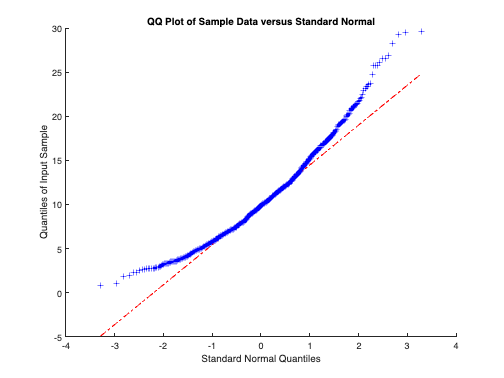

figure(2)
qqplot(mbare3)
ylabel('Quantiles of Input Sample');
xlabel('Standard Normal Quantiles');

### Explain why or why not the averages are approximately normally distributed in each case.

In this case the averages are not approximately normally distributed in each case because the histogram shows  that the distribution is skewed. The data points enclosed in the area under the curve which can be drawn on the histogram, are very close to the mean at one side, and far from the mean on the other side. And also since the graphical test from the Q-Q plot doesn't depeicts  a straight line for the quantile data and standard normal quantiles.

## No.4 Repeat the experiment in 3.

### Generate 50 exponentially distributed random numbers.

nn = 50; % 50 exponentially distributed random numbers

[mbare4] = generate(nn);

### Plot a histogram of the 1000 average

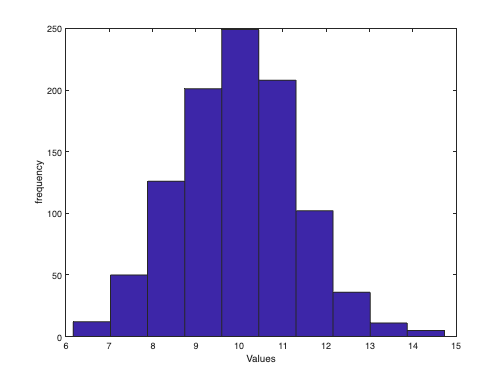

% plot a histogram
figure(3)
hist(mbare4)
ylabel('frequency');
xlabel('Values');

### Make a Q-Q plot of the 1000 averages

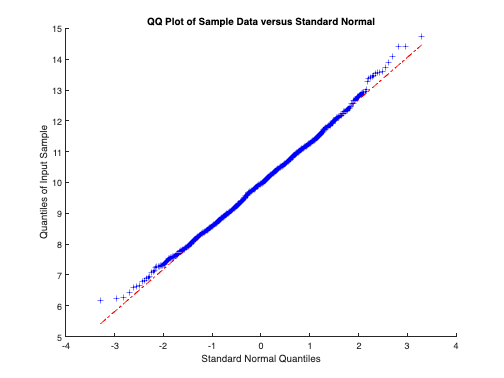

figure(4)
qqplot(mbare4)
ylabel('Quantiles of Input Sample');
xlabel('Standard Normal Quantiles');

### Explain why or why not the averages are approximately normally distributed in each case.

In this case the averages are approximately normally distributed because the histogram shows a roughly bell-shaped distribution and its symmetrical around a single peak. The data points enclosed in the area under the curve which can be drawn on the histogram, are very close to the mean, and are at almost equal distances from each either sides of the mean. And also since the graphical test from the Q-Q plot depeicts that the quantile data and standard normal quantiles almost follow a straight line.

function [mbare] = generate(nn)
    N = 1000;
    
    mbare = zeros(N,1);
    
    for i=1:N
        expd = exprnd(10,nn,1); % nn exponentially distributed random numbers
        mbare(i) = mean(expd); % mean of the five numbers
    end
end